clear all
close all
clc

1st image

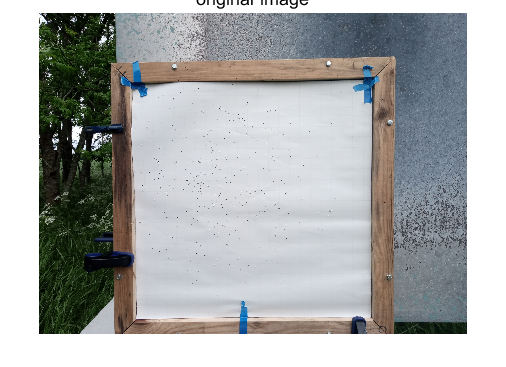

I_1 = imread('IMG1.jpg');
figure, imshow(I_1)
title('original image')

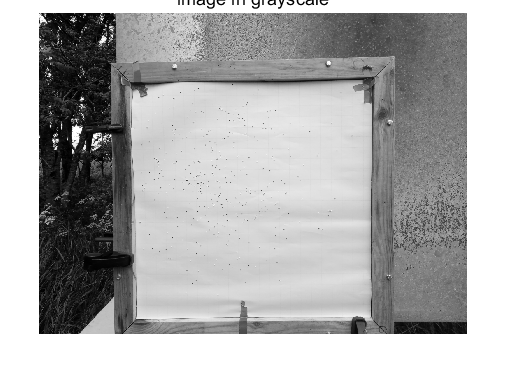

% convert the image into the gray scale
IRed_1 = double(I_1(:,:,1));          
IGreen_1 = double(I_1(:,:,2));
IBlue_1 = double(I_1(:,:,3));
IGrey_1 = (IRed_1+IGreen_1+IBlue_1)/3;
I_1 = uint8(IGrey_1);
% get the size of the image
I_1=double(I_1);
[m,n]=size(I_1);

% Gaussian filter
Igaussian_1 = zeros(m,n);
for i = 2:m-1                                                       
    for j = 2:n-1
        Igaussian_1(i,j) = (I_1(i-1,j-1)+2*I_1(i-1,j)+I_1(i-1,j+1) ...
            +2*I_1(i,j-1)+4*I_1(i,j)+2*I_1(i,j+1) ...
            +I_1(i+1,j-1)+2*I_1(i+1,j)+I_1(i+1,j+1))/16;
    end
end
Igaussian_1 = uint8(Igaussian_1);
figure,imshow(Igaussian_1)
title('image in grayscale')

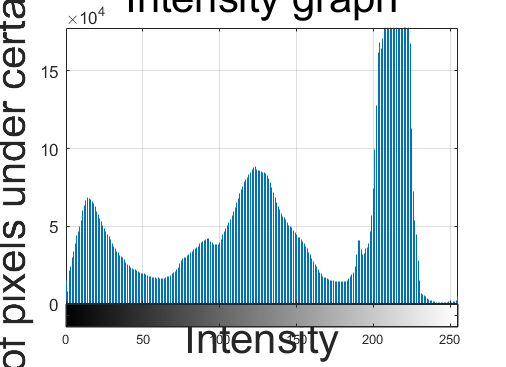


imhist(Igaussian_1)
xlabel('Intensity',FontSize=25)
ylabel('Number of pixels under certain intensity',FontSize=25)
title('Intensity graph',FontSize=25)
grid on

% thresholding %
Ithresholding_1 = zeros(m,n);
for i = 1:m
    for j = 1:n
        if Igaussian_1(i,j) > 180
            Ithresholding_1(i,j) = 0;
        else
            Ithresholding_1(i,j) = 255;
        end
    end
end
Ithresholding_1 = uint8(Ithresholding_1);
figure,imshow(Ithresholding_1)

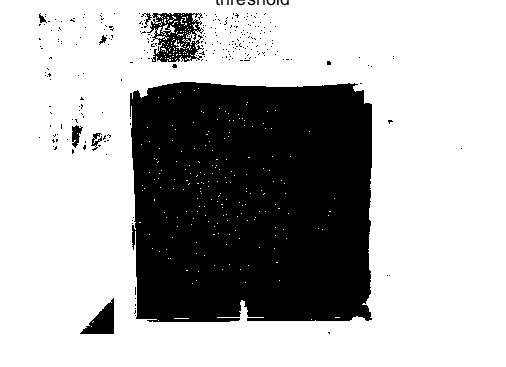

title('threshold')

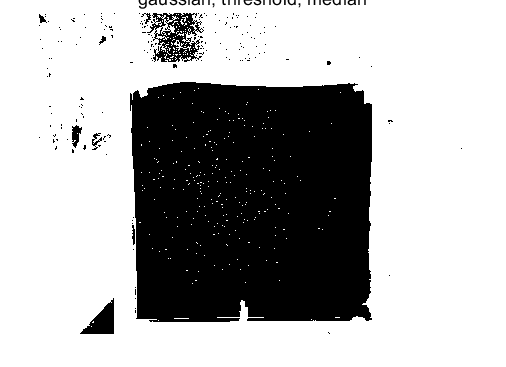


% median filter
Imedian_1 =zeros(m,n);
for i = 2:m-1
    for j = 2:n-1
        Imedian_1(i,j) = median([Ithresholding_1(i-1,j-1)+Ithresholding_1(i-1,j)+Ithresholding_1(i-1,j+1) ...
            +Ithresholding_1(i,j-1)+Ithresholding_1(i,j)+Ithresholding_1(i,j+1) ...
            +Ithresholding_1(i+1,j-1)+Ithresholding_1(i+1,j)+Ithresholding_1(i+1,j+1)]);
    end
end
Imedian_1 = uint8(Imedian_1);
figure,imshow(Imedian_1)
title('gaussian, threshold, median')

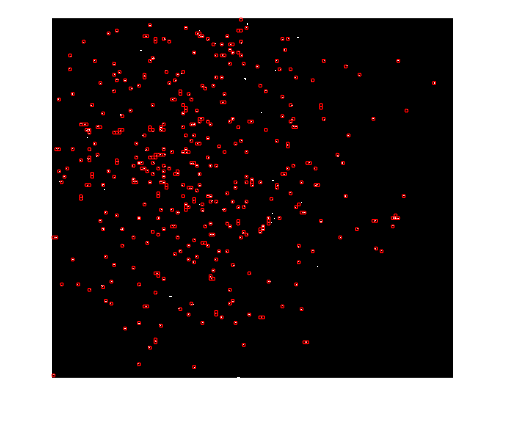


Iinner_1 = imcrop(Imedian_1,[962.5 842.5 2180 1956]);
% Iinner_1 = imcrop(Imedian_1);
figure,imshow(Iinner_1)

% findin the holes
count_1x = 0;
ele = 1;
intervali = 15;
intervalj = 15;
for i = 1:intervali:1956-intervali
    for j = 1:intervalj:2180-intervalj
        Ibox_1 = Iinner_1(i:i+intervali,j:j+intervalj);
        density_1= sum(sum(Ibox_1));
        
        if density_1 > 30*255
            rectangle('Position',[j i intervalj intervali],'EdgeColor','r')
            count_1x = count_1x + 1;
        end
        histx_1(ele) = count_1x;
    end
    count_1x = 0;
    ele = ele + 1;
end

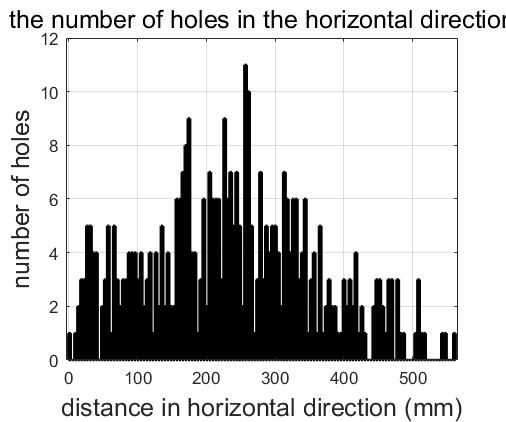

count_1y = 0;
ele = 1;
count_all_1 = 0;
for j = 1:intervalj:2180-intervalj
    for i = 1:intervali:1956-intervali
        Ibox_1 = Iinner_1(i:i+intervali,j:j+intervalj);
        density_1 = sum(sum(Ibox_1));
        if density_1 > 30*255
            count_1y = count_1y + 1;
            count_all_1 = count_all_1 + 1;
        end
        histy_1(ele) = count_1y;
    end
    count_1y = 0;
    ele = ele + 1;
end

x_axis_1 = 1:(564/130):564;
bar(x_axis_1,histx_1,LineWidth=1.5)
xlabel('distance in horizontal direction (mm)',FontSize=15)
ylabel('number of holes',FontSize=15)
title('the number of holes in the horizontal direction',FontSize=15)
grid on

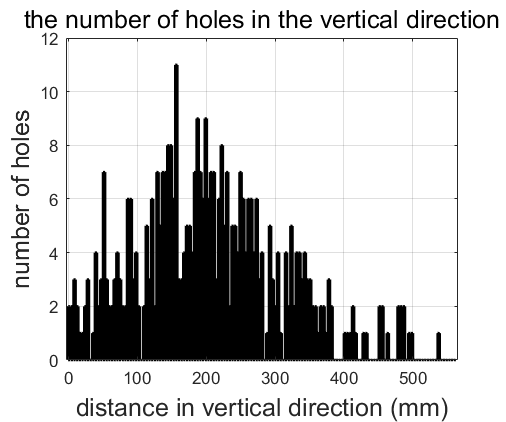

y_axis_1 = 1:(564/145):564;
bar(y_axis_1,histy_1,LineWidth=1.5)
xlabel('distance in vertical direction (mm)',FontSize=15)
ylabel('number of holes',FontSize=15)
title('the number of holes in the vertical direction',FontSize=15)
grid on

2nd image

I_2 = imread('IMG2.jpg');
figure, imshow(I_2)
title('original image')
% convert the image into the gray scale
IRed_2 = double(I_2(:,:,1));          
IGreen_2 = double(I_2(:,:,2));
IBlue_2 = double(I_2(:,:,3));
IGrey_2 = (IRed_2+IGreen_2+IBlue_2)/3;
I_2 = uint8(IGrey_2);
% get the size of the image
I_2=double(I_2);
[m,n]=size(I_2);

% Gaussian filter
Igaussian_2 = zeros(m,n);
for i = 2:m-1                                                       
    for j = 2:n-1
        Igaussian_2(i,j) = (I_2(i-1,j-1)+2*I_2(i-1,j)+I_2(i-1,j+1) ...
            +2*I_2(i,j-1)+4*I_2(i,j)+2*I_2(i,j+1) ...
            +I_2(i+1,j-1)+2*I_2(i+1,j)+I_2(i+1,j+1))/16;
    end
end
Igaussian_2 = uint8(Igaussian_2);

% thresholding %
Ithresholding_2 = zeros(m,n);
for i = 1:m
    for j = 1:n
        if Igaussian_2(i,j) > 175
            Ithresholding_2(i,j) = 0;
        else
            Ithresholding_2(i,j) = 255;
        end
    end
end
Ithresholding_2 = uint8(Ithresholding_2);
figure,imshow(Ithresholding_2)
title('threshold')

% median filter
Imedian_2 =zeros(m,n);
for i = 2:m-1
    for j = 2:n-1
        Imedian_2(i,j) = median([Ithresholding_2(i-1,j-1)+Ithresholding_2(i-1,j)+Ithresholding_2(i-1,j+1) ...
            +Ithresholding_2(i,j-1)+Ithresholding_2(i,j)+Ithresholding_2(i,j+1) ...
            +Ithresholding_2(i+1,j-1)+Ithresholding_2(i+1,j)+Ithresholding_2(i+1,j+1)]);
    end
end
Imedian_2 = uint8(Imedian_2);
figure,imshow(Imedian_2)
title('gaussian, threshold, median')

Iinner_2 = imcrop(Imedian_2,[1054.5 455.5 2232 2165]);
figure,imshow(Iinner_2)

% findin the holes
count_2x = 0;
ele = 1;
for i = 1:15:2166-15
    for j = 1:15:2233-15
        Ibox_2 = Iinner_2(i:i+15,j:j+15);
        density_2 = sum(sum(Ibox_2));
        if density_2 > 30*255
            rectangle('Position',[j i 15 15],'EdgeColor','r')
            count_2x = count_2x + 1;
        end
        histx_2(ele) = count_2x;
    end
    count_2x = 0;
    ele = ele + 1;
end
count_2y = 0;
ele = 1;
for j = 1:15:2166-15
    for i = 1:15:2233-15
        Ibox_2 = Iinner_2(i:i+15,j:j+15);
        density_2 = sum(sum(Ibox_2));
        if density_2 > 30*255
            rectangle('Position',[j i 15 15],'EdgeColor','r')
            count_2y = count_2y + 1;
        end
        histy_2(ele) = count_2y;
    end
    count_2y = 0;
    ele = ele + 1;
end

x_axis_2 = 1:(564/130):564;
bar(x_axis_2,histx_2,LineWidth=1.5)
xlabel('distance in horizontal direction (mm)',FontSize=15)
ylabel('number of holes',FontSize=15)
title('the number of holes in the horizontal direction',FontSize=15)
grid on
y_axis_2 = 1:(564/145):564;
bar(y_axis_2,histy_2,LineWidth=1.5)
xlabel('distance in vertical direction (mm)',FontSize=15)
ylabel('number of holes',FontSize=15)
title('the number of holes in the vertical direction',FontSize=15)
grid on

3rd image

I_3 = imread('IMG3.jpg');
figure, imshow(I_3)
title('original image')
% convert the image into the gray scale
IRed_3 = double(I_3(:,:,1));          
IGreen_3 = double(I_3(:,:,2));
IBlue_3 = double(I_3(:,:,3));
IGrey_3 = (IRed_3+IGreen_3+IBlue_3)/3;
I_3 = uint8(IGrey_3);
% get the size of the image
I_3=double(I_3);
[m,n]=size(I_3);

% Gaussian filter
Igaussian_3 = zeros(m,n);
for i = 2:m-1                                                       
    for j = 2:n-1
        Igaussian_3(i,j) = (I_3(i-1,j-1)+2*I_3(i-1,j)+I_3(i-1,j+1) ...
            +2*I_3(i,j-1)+4*I_3(i,j)+2*I_3(i,j+1) ...
            +I_3(i+1,j-1)+2*I_3(i+1,j)+I_3(i+1,j+1))/16;
    end
end
Igaussian_3 = uint8(Igaussian_3);

% thresholding %
Ithresholding_3 = zeros(m,n);
for i = 1:m
    for j = 1:n
        if Igaussian_3(i,j) > 180
            Ithresholding_3(i,j) = 0;
        else
            Ithresholding_3(i,j) = 255;
        end
    end
end
Ithresholding_3 = uint8(Ithresholding_3);
figure,imshow(Ithresholding_3)
title('threshold')

% median filter
Imedian_3 =zeros(m,n);
for i = 2:m-1
    for j = 2:n-1
        Imedian_3(i,j) = median([Ithresholding_3(i-1,j-1)+Ithresholding_3(i-1,j)+Ithresholding_3(i-1,j+1) ...
            +Ithresholding_3(i,j-1)+Ithresholding_3(i,j)+Ithresholding_3(i,j+1) ...
            +Ithresholding_3(i+1,j-1)+Ithresholding_3(i+1,j)+Ithresholding_3(i+1,j+1)]);
    end
end
Imedian_3 = uint8(Imedian_3);
figure,imshow(Imedian_3)
title('gaussian, threshold, median')

Iinner_3 = imcrop(Imedian_3,[962.5 490.5 2256 2092]);
figure,imshow(Iinner_3)

% findin the holes
count_3x = 0;
ele = 1;
for i = 1:20:2093-20
    for j = 1:20:2257-20
        Ibox_3 = Iinner_3(i:i+20,j:j+20);
        density_3 = sum(sum(Ibox_3));
        if density_3 > 15*255
            rectangle('Position',[j i 20 20],'EdgeColor','r')
            count_3x = count_3x + 1;
        end
        histx_3(ele) = count_3x;
    end
    count_3x = 0;
    ele = ele + 1;
end
count_3y = 0;
ele = 1;
for j = 1:20:2257-20
    for i = 1:20:2093-20
        Ibox_3 = Iinner_3(i:i+20,j:j+20);
        density_3 = sum(sum(Ibox_3));
        if density_3 > 15*255
            rectangle('Position',[j i 20 20],'EdgeColor','r')
            count_3y = count_3y + 1;
        end
        histy_3(ele) = count_3y;
    end
    count_3y = 0;
    ele = ele + 1;
end
histogram(histx_3,LineWidth=1.5)
xlabel('distance in x direction',FontSize=15)
ylabel('number of holes',FontSize=15)
title('the number of holes in the direction of x',FontSize=15)
grid on
histogram(histy_3,LineWidth=1.5)
xlabel('distance in y direction',FontSize=15)
ylabel('number of holes',FontSize=15)
title('the number of holes in the direction of y',FontSize=15)
grid on

4th image dont know yet

I_4 = imread('IMG4.jpg');
figure, imshow(I_4)
title('original image')
convert the image into the gray scale
IRed_4 = double(I_4(:,:,1));          
IGreen_4 = double(I_4(:,:,2));
IBlue_4 = double(I_4(:,:,3));
IGrey_4 = (IRed_4+IGreen_4+IBlue_4)/3;
I_4 = uint8(IGrey_4);
get the size of the image
I_4=double(I_4);
[m,n]=size(I_4);

Gaussian filter
Igaussian_4 = zeros(m,n);
for i = 2:m-1                                                       
    for j = 2:n-1
        Igaussian_4(i,j) = (I_4(i-1,j-1)+2*I_4(i-1,j)+I_4(i-1,j+1) ...
            +2*I_4(i,j-1)+4*I_4(i,j)+2*I_4(i,j+1) ...
            +I_4(i+1,j-1)+2*I_4(i+1,j)+I_4(i+1,j+1))/16;
    end
end
Igaussian_4 = uint8(Igaussian_4);

thresholding %
Ithresholding_4 = zeros(m,n);
for i = 1:m
    for j = 1:n
        if Igaussian_4(i,j) > 155
            Ithresholding_4(i,j) = 0;
        else
            Ithresholding_4(i,j) = 255;
        end
    end
end
Ithresholding_4 = uint8(Ithresholding_4);
figure,imshow(Ithresholding_4)
title('threshold')

median filter
Imedian_4 =zeros(m,n);
for i = 2:m-1
    for j = 2:n-1
        Imedian_4(i,j) = median([Ithresholding_4(i-1,j-1)+Ithresholding_4(i-1,j)+Ithresholding_4(i-1,j+1) ...
            +Ithresholding_4(i,j-1)+Ithresholding_4(i,j)+Ithresholding_4(i,j+1) ...
            +Ithresholding_4(i+1,j-1)+Ithresholding_4(i+1,j)+Ithresholding_4(i+1,j+1)]);
    end
end
Imedian_4 = uint8(Imedian_4);
figure,imshow(Imedian_4)
title('gaussian, threshold, median')

Iinner_4 = imcrop(Imedian_4);
figure,imshow(Iinner_4)

findin the holes
count_4 = 0;
for i = 1:20:1801-20
    for j = 1:20:2201-20
        Ibox_4 = Iinner_4(i:i+20,j:j+20);
        density_4 = sum(sum(Ibox_4));
        if density_4 > 15*255
            rectangle('Position',[j i 20 20],'EdgeColor','r')
            count_4 = count_4 + 1;
        end
    end
end

5th image dont know yet

I_5 = imread('IMG5.jpg');
figure, imshow(I_5)
title('original image')
% convert the image into the gray scale
IRed_5 = double(I_5(:,:,1));          
IGreen = double(I_5(:,:,2));
IBlue = double(I_5(:,:,3));
IGrey = (IRed_5+IGreen+IBlue)/3;
I_5 = uint8(IGrey);
% get the size of the image
I_5=double(I_5);
[m,n]=size(I_5);

% Gaussian filter
Igaussian_5 = zeros(m,n);
for i = 2:m-1                                                       
    for j = 2:n-1
        Igaussian_5(i,j) = (I_5(i-1,j-1)+2*I_5(i-1,j)+I_5(i-1,j+1) ...
            +2*I_5(i,j-1)+4*I_5(i,j)+2*I_5(i,j+1) ...
            +I_5(i+1,j-1)+2*I_5(i+1,j)+I_5(i+1,j+1))/16;
    end
end
Igaussian_5 = uint8(Igaussian_5);

% thresholding %
Ithresholding_5 = zeros(m,n);
for i = 1:m
    for j = 1:n
        if Igaussian_5(i,j) > 180
            Ithresholding_5(i,j) = 0;
        else
            Ithresholding_5(i,j) = 255;
        end
    end
end
Ithresholding_5 = uint8(Ithresholding_5);
figure,imshow(Ithresholding_5)
title('threshold')

% median filter
Imedian_5 =zeros(m,n);
for i = 2:m-1
    for j = 2:n-1
        Imedian_5(i,j) = median([Ithresholding_5(i-1,j-1)+Ithresholding_5(i-1,j)+Ithresholding_5(i-1,j+1) ...
            +Ithresholding_5(i,j-1)+Ithresholding_5(i,j)+Ithresholding_5(i,j+1) ...
            +Ithresholding_5(i+1,j-1)+Ithresholding_5(i+1,j)+Ithresholding_5(i+1,j+1)]);
    end
end
Imedian_5 = uint8(Imedian_5);
figure,imshow(Imedian_5)
title('gaussian, threshold, median')

Iinner_5 = imcrop(Imedian_5,[950 880 2200 1800]);
figure,imshow(Iinner_5)

% findin the holes
count_5 = 0;
for i = 1:20:1801-20
    for j = 1:20:2201-20
        Ibox_5 = Iinner_5(i:i+20,j:j+20);
        density_5 = sum(sum(Ibox_5));
        if density_5 > 15*255
            rectangle('Position',[j i 20 20],'EdgeColor','r')
            count_5 = count_5 + 1;
        end
    end
end

6th image dont know yet

I_6 = imread('IMG6.jpg');
figure, imshow(I_6)
title('original image')
% convert the image into the gray scale
IRed_6 = double(I_6(:,:,1));          
IGreen_6 = double(I_6(:,:,2));
IBlue_6 = double(I_6(:,:,3));
IGrey_6 = (IRed_6+IGreen_6+IBlue_6)/3;
I_6 = uint8(IGrey_6);
% get the size of the image
I_6=double(I_6);
[m,n]=size(I_6);

% Gaussian filter
Igaussian_6 = zeros(m,n);
for i = 2:m-1                                                       
    for j = 2:n-1
        Igaussian_6(i,j) = (I_6(i-1,j-1)+2*I_6(i-1,j)+I_6(i-1,j+1) ...
            +2*I_6(i,j-1)+4*I_6(i,j)+2*I_6(i,j+1) ...
            +I_6(i+1,j-1)+2*I_6(i+1,j)+I_6(i+1,j+1))/16;
    end
end
Igaussian_6 = uint8(Igaussian_6);

% thresholding %
Ithresholding_6 = zeros(m,n);
for i = 1:m
    for j = 1:n
        if Igaussian_6(i,j) > 180
            Ithresholding_6(i,j) = 0;
        else
            Ithresholding_6(i,j) = 255;
        end
    end
end
Ithresholding_6 = uint8(Ithresholding_6);
figure,imshow(Ithresholding_6)
title('threshold')

% median filter
Imedian_6 =zeros(m,n);
for i = 2:m-1
    for j = 2:n-1
        Imedian_6(i,j) = median([Ithresholding_6(i-1,j-1)+Ithresholding_6(i-1,j)+Ithresholding_6(i-1,j+1) ...
            +Ithresholding_6(i,j-1)+Ithresholding_6(i,j)+Ithresholding_6(i,j+1) ...
            +Ithresholding_6(i+1,j-1)+Ithresholding_6(i+1,j)+Ithresholding_6(i+1,j+1)]);
    end
end
Imedian_6 = uint8(Imedian_6);
figure,imshow(Imedian_6)
title('gaussian, threshold, median')

Iinner_6 = imcrop(Imedian_6);
figure,imshow(Iinner_6)

% findin the holes
count_6 = 0;
for i = 1:20:1801-20
    for j = 1:20:2201-20
        Ibox_6 = Iinner_6(i:i+20,j:j+20);
        density_6 = sum(sum(Ibox_6));
        if density_6 > 15*255
            rectangle('Position',[j i 20 20],'EdgeColor','r')
            count_6 = count_6 + 1;
        end
    end
end

